# Further Analysis of MathWorks Solar Array Production

This script extends the analysis of solar panel production in `solarproduction_model.mlx` to consider the whole month of June and compare the production from the two arrays (one on the "Apple Hill 3" building and the other on the "Lakeside Parking" building).

Copyright 2019 The MathWorks, Inc.

## Model energy production for the month of June

Create row vector of days of the year and column vector of times of day.

d = 152:181;
t = (0:0.25:23.75)';

Calculate declination for each day. Define latitude.

dec = deg2rad(23.45*cosd(360/365*(d-172)));
lat = deg2rad(42 + 17/60);

Shift time to local solar time.

LST = t - 1 + 14.6/60;

Calculate elevation of the sun for each day & time.

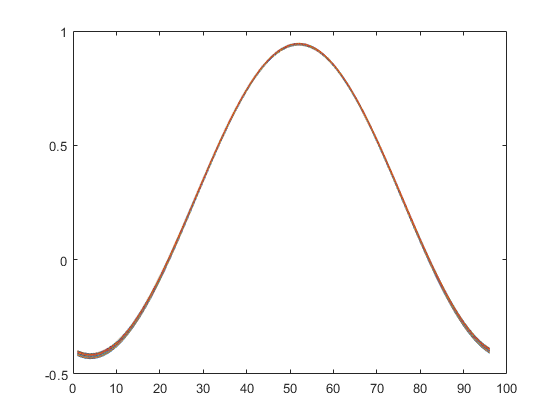

sunangle = sin(dec)*sin(lat) + cos(dec)*cos(lat).*cosd(15*(LST - 12));
plot(sunangle)

Negative angle means the sun is below the horizon. To keep the math simple, set all negative angles to zero.

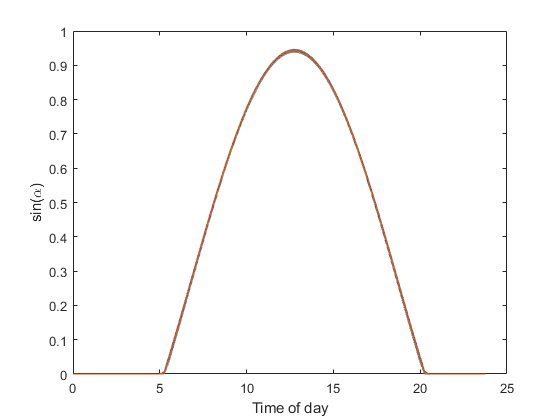

sunangle(sunangle<0) = 0;
plot(t,sunangle)
xlabel('Time of day')
ylabel('sin(\alpha)')

Caculate energy incident on the panels.

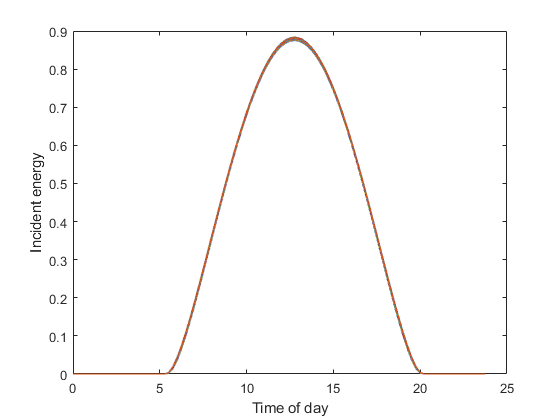

s_inc = 1.353*0.7.^(sunangle.^-0.678);
prod_theory = s_inc.*sunangle;
plot(t,prod_theory)
xlabel('Time of day')
ylabel('Incident energy')

Not a lot of variation from day to day.

Extract the maximum across all days in the month.

theorymax = max(prod_theory,[],2);

## Compare to recorded data

Import actual data.

production = readtable("SolarArrayProduction.xlsx");

Add the theoretical production for both arrays (one for the "Apple Hill 3" building, one for the "Lakeside Parking" building) for the whole month.

Note the use of `(:)` to unroll the matrix [day-by-time] into one vector.

theorymaxAH3 = min(271*prod_theory,207);
theorymaxLSP = min(635*prod_theory,485);
production.theoryAH3 = theorymaxAH3(:);
production.theoryLSP = theorymaxLSP(:);
% Now take the max over all days
theorymaxAH3 = max(theorymaxAH3,[],2);
theorymaxLSP = max(theorymaxLSP,[],2);

Compare theory and data.

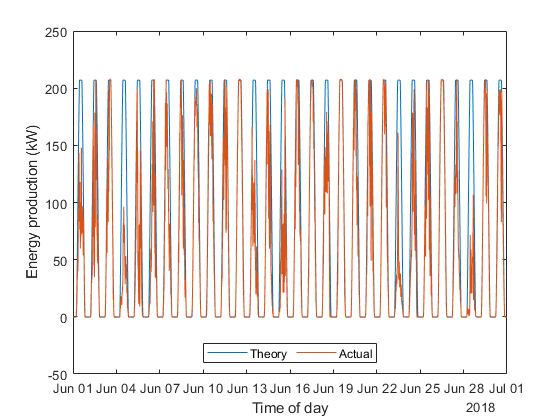

plot(production.Timestamp,production{:,{'theoryAH3','AH3'}})
xlabel('Time of day')
ylabel('Energy production (kW)')
legend('Theory','Actual','Location','south','Orientation','horizontal')

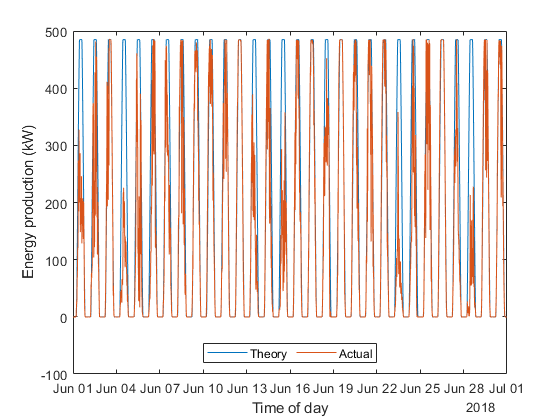

plot(production.Timestamp,production{:,{'theoryLSP','LSParking'}})
xlabel('Time of day')
ylabel('Energy production (kW)')
legend('Theory','Actual','Location','south','Orientation','horizontal')

## Calculate statistics for the month

View production as a function of time-of-day, for all days.

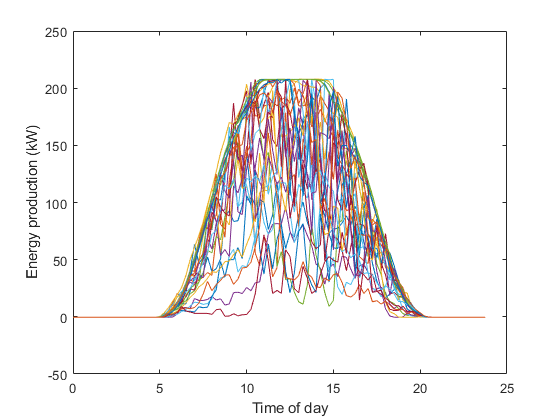

AH3actual = reshape(production.AH3,96,30);
plot(t,AH3actual)
xlabel('Time of day')
ylabel('Energy production (kW)')

Now calculate average daily production, averaged over the month.

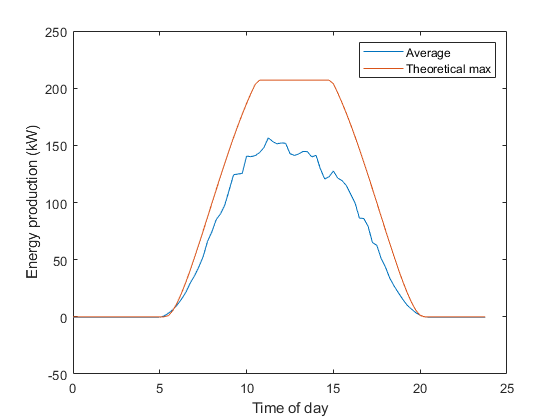

plot(t,mean(AH3actual,2),t,theorymaxAH3)
xlabel('Time of day')
ylabel('Energy production (kW)')
legend('Average','Theoretical max')

#### Visualize typical operating range

Calculate quartiles and perform some smoothing.

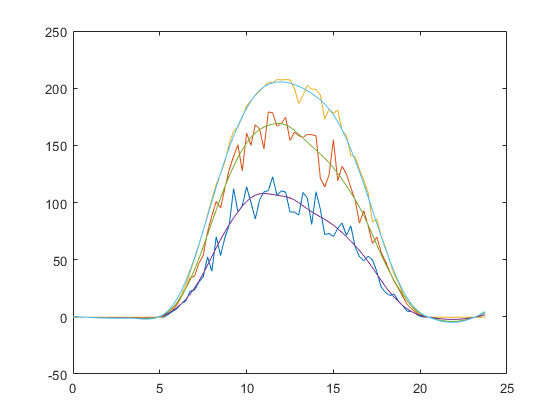

quarts = quantile(AH3actual,[.25 .5 .75],2);
qs_smooth = smoothdata(quarts,"loess");
plot(t,quarts,t,qs_smooth)

Plot a representation of the range along with the theoretical max.

plot(t,theorymaxAH3)
xlabel('Time of day')
ylabel('Energy production (kW)')
% Add the median
hold on
plot(t,qs_smooth(:,2))

Use area to make plot of stacked shaded areas. "Baseline" is first quartile. On top of that is a shaded area with width = interquartile range (= 75% - 25%)

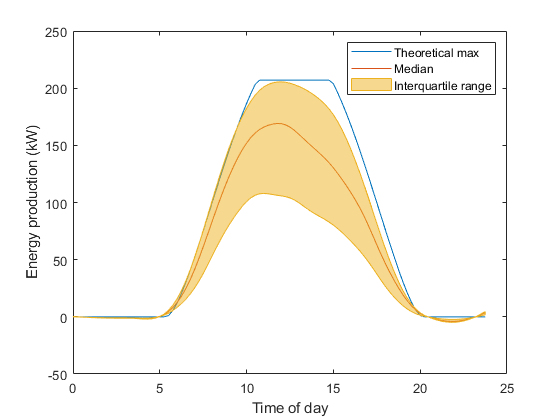

a = area(t,[qs_smooth(:,1) qs_smooth(:,3)-qs_smooth(:,1)]);
% Don't actually want the first shaded area
a(1).Visible = 'off';
% Do some fine-tuning of the colors and shading
a(2).FaceColor = a(1).FaceColor;
a(2).EdgeColor = a(2).FaceColor;
a(2).FaceAlpha = 0.5;
% Turn off the horizontal line at the bottom of the plot
a(2).BaseLine.LineStyle = 'none';

% Add legend. Note that there's an invisible plot element. This will mess
% up the legend, so get all the plot objects and give the desired set to
% the legend function
ax = gca;
legend(ax.Children([4 3 1]),'Theoretical max','Median','Interquartile range')

hold off

## Compare production of two separate arrays

The two buildings are separated by a couple of miles. Overall the weather (and therefore production) should be similar. But local effects may make some difference.

#### Compare the raw total production

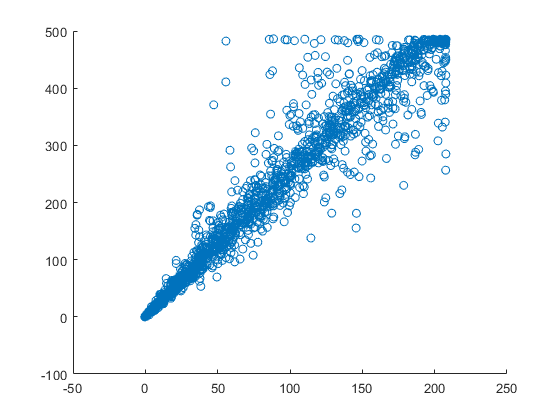

scatter(production.AH3,production.LSParking)

corrcoef(production.AH3,production.LSParking)

ans =     1.0000    0.9796
    0.9796    1.0000


As expected, there's a strong linear correlation. Fit a line:

prodmodel = fitlm(production.AH3,production.LSParking)

prodmodel = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________
    (Intercept)     5.5934       0.80065    6.9862    3.4955e-12
    x1              2.3974     0.0091638    261.62             0

Number of observations: 2880, Error degrees of freedom: 2878
Root Mean Squared Error: 33.6
R-squared: 0.96,  Adjusted R-Squared: 0.96
F-statistic vs. constant model: 6.84e+04, p-value = 0

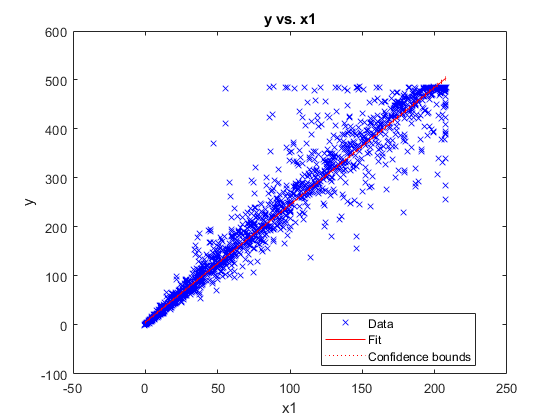

plot(prodmodel)

#### Compare the production relative to the theoretical maximum

Calculate the proportion of energy produced to theoretical maximum production.

percAH3 = production.AH3./production.theoryAH3;
percLSP = production.LSParking./production.theoryLSP;

Small instrumentation errors can result in values outside the range of [0 1]. Remove these.

percAH3(percAH3 < 0 | percAH3 > 1) = NaN;
percLSP(percLSP < 0 | percLSP > 1) = NaN;

Compare the two arrays

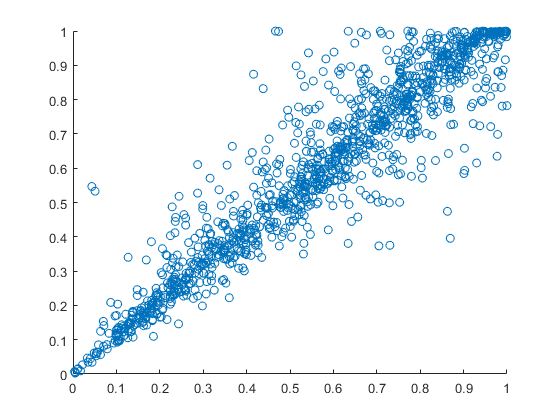

scatter(percAH3,percLSP)

corrcoef(percAH3,percLSP,"Rows","complete")  % ignore NaNs

ans =     1.0000    0.9361
    0.9361    1.0000


Again, a strong linear correlation.

prodmodel = fitlm(percAH3,percLSP)

prodmodel = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________
    (Intercept)    0.052717    0.0064298    8.1989    5.9965e-16
    x1               0.9617     0.010253    93.795             0

Number of observations: 1243, Error degrees of freedom: 1241
Root Mean Squared Error: 0.0949
R-squared: 0.876,  Adjusted R-Squared: 0.876
F-statistic vs. constant model: 8.8e+03, p-value = 0

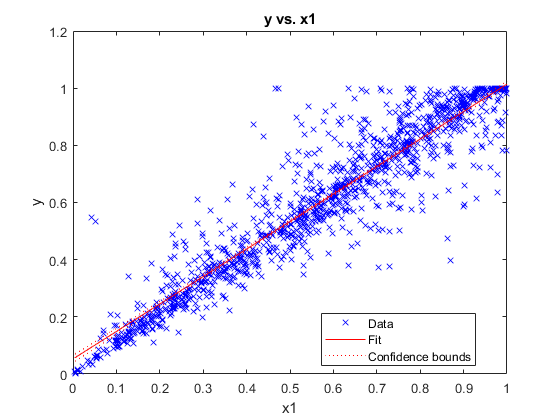

plot(prodmodel)

Slope is close to 1, intercept close to 0, as expected.